clearvars;
parpool;

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 4).


% Init param
M = 128;
[x, q]= PAM_generator(M); % for equiprobable symbols

N = 2;
[z,w] = GaussHermite_Locations_Weights(N);

SNR = 1.0;

rho = 0;
max_rho = 1;
delta = 0.001;
E0_values = [];  % Pel display
rho_values = []; % Pel display

E0_values_par = [];  % Pel display
rho_values_par = linspace(0, 1, 1000);

maxE0 = -Inf;
best_rho = -1;

[Q, pi_, G] = matrix_generator(N, q, x, w, z, SNR);

% E0 computation with matrices
 % Time start -----------------------------------------------
tic;
while rho <= max_rho
    E0_i = E0_matrix(Q, pi_, G, rho);
    E0_values = [E0_values, E0_i];      % Pel display
    rho_values = [rho_values, rho];     % Pel display                
    rho = rho + delta;
end

elapsed_time = toc; % ------------------------------------------
disp(['Temps execució: ', num2str(elapsed_time), ' segons']);

Temps execució: 2.0886 segons


% E0 computation with matrices
 % Time start -----------------------------------------------
tic;
parfor rho_idx = 1:length(rho_values_par)
    E0_i = E0_matrix(Q, pi_, G, rho_idx);
    E0_values_par = [E0_values_par, E0_i];      % Pel display
    rho_values_par = [rho_values_par, rho_idx];     % Pel display                
end

elapsed_time = toc; % ------------------------------------------
disp(['Temps execució: ', num2str(elapsed_time), ' segons']);

Temps execució: 2.3069 segons


% Display
disp("Rho for which E0 is max:");

Rho for which E0 is max:


disp(best_rho);

    -1



disp("It gives us a value of E0 = ")

It gives us a value of E0 = 


disp(maxE0);

  -Inf



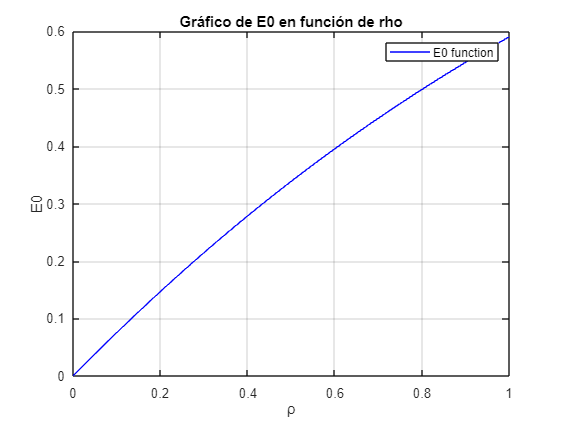


% Gràfica d'E0 respecte rho
plot(rho_values, E0_values, 'b', 'DisplayName', 'E0 function');
xlabel('ρ');
ylabel('E0');
title('Gráfico de E0 en función de rho');
legend;
grid on;

% Find best rho
tic;
[max, idx]= max(E0_values);
disp(['E0 max value:', num2str(max)])

E0 max value:0.59037


best_rho = delta * idx;
disp(['Rho:', num2str(best_rho)])

Rho:1


elapsed_time = toc; % ------------------------------------------
disp(['Temps execució: ', num2str(elapsed_time), ' segons']);

Temps execució: 0.01798 segons


% % Per E0(1)
% %[Q, pi_, G] = matrix_generator(N, q, x, w, z, SNR);
% tic;
% E = E0_matrix(Q, pi_, G, 1);
% elapsed_time = toc; % ------------------------------------------
% disp(['Temps execució: ', num2str(elapsed_time), ' segons']);
% disp(E)